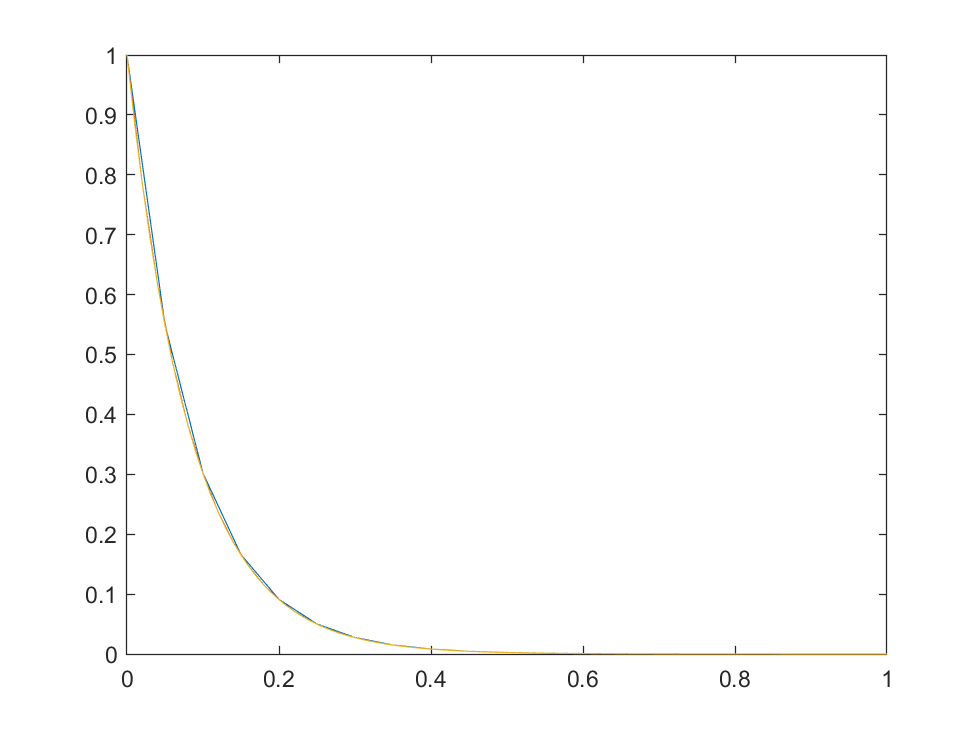

f =@(t,y) (-12*y);
F =@(t) (exp(-12*t));

a = 0;
b = 1;

alpha = 1;

N = [20,50,100];

y3 = RK4(f,a,b,alpha,N(1,1));
y4 = RK4(f,a,b,alpha,N(1,2));
y5 = RK4(f,a,b,alpha,N(1,3));

x3 = (b-a)/N(1,1);
x4 = (b-a)/N(1,2);
x5 = (b-a)/N(1,3);

t3 = a:x3:b;
t4 = a:x4:b;
t5 = a:x5:b;

t3 = t3';
t4 = t4';
t5 = t5';

plot(t3,y3,t4,y4,t5,y5);

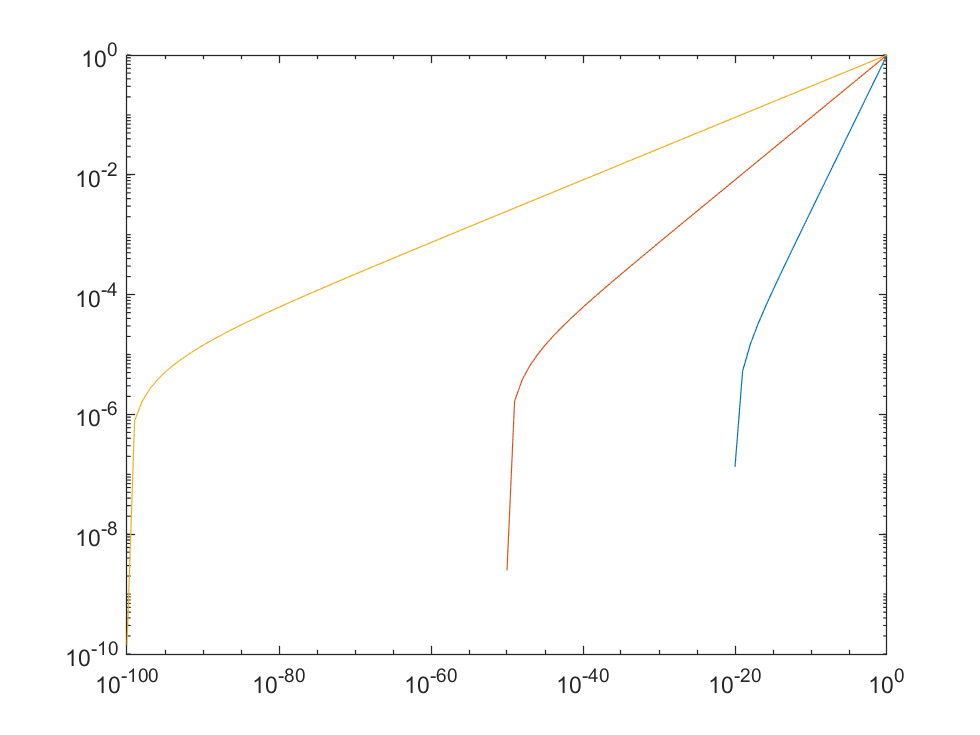


% the answer gets more accurate as the number of intervals increases

syms y(t)
eqn = diff(y,t) == (-12*y);
cond = y(0) == alpha;
ySol(t) = dsolve(eqn,cond);

eans = vpa(ySol(1));

h3 = ones(1,N(1,1)+1);
h4 = ones(1,N(1,2)+1);
h5 = ones(1,N(1,3)+1);

err3 = ones(1,N(1,1)+1);
err4 = ones(1,N(1,2)+1);
err5 = ones(1,N(1,3)+1);

% absolute error of 20 intervals
for i = 1:N(1,1)+1
    h3(1,i) = 10^(1-i);
    err3(1,i) = abs(eans-y3(i,1));
end

% absolute error of 50 intervals
for i = 1:N(1,2)+1
    h4(1,i) = 10^(1-i);
    err4(1,i) = abs(eans-y4(i,1));
end

% absolute error of 100 intervals
for i = 1:N(1,3)+1
    h5(1,i) = 10^(1-i);
    err5(1,i) = abs(eans-y5(i,1));
end

loglog(h3,err3);
hold on;
loglog(h4,err4);
loglog(h5,err5);
hold off;


Err1 = [err3(1,N(1,1)+1),err4(1,N(1,2)+1),err5(1,N(1,3)+1)];

% the error decreases as the number of intervals increases
% the method appears to be converging


function [y] = RK4(f,a,b,alpha,N)
    h = (b-a)/N;
    x = a:h:b;
    sx = size(x,2);
    y = ones(1,sx);
    y(1,1) = alpha;
    for i = 2:N+1
        k1 = h*f(x(1,i-1),y(1,i-1));
        k2 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k1/2));
        k3 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k2/2));
        k4 = h*f(x(1,i),y(1,i-1) + k3);
        y(1,i) = y(1,i-1) + (k1/6) + (k2/3) + (k3/3) + (k4/6);
    end
    y = y';
end
